# Regresión por mínimos cuadrados

La toma de datos durante una experimentación o durante un análisis se ve siempre afectada por los **errores** que puedan existir debido a **variables que no podemos controlar** y de las cuales desconocemos su comportamiento. Los datos resultantes podrían presentar **errores inerentes al fenómeno** que estudiamos y por lo tanto no siguen **la tendencia** que se esperaría. Es por ello que, en lugar de utilizar una interpolación entre los puntos, se requiere de **una aproximación** bajo una tendencia que esté de acuerdo **al modelo matemático** que describa el fenómeno observado.

## Regresión lineal

A uno de los** métodos** para ajusta el modelo aproximado a los datos obtenidos se le conoce como **regresión por mínimos cuadrados**. El ejemplo mas sencillo se da cuando queremos ajustar la tendencia de una linea recta a un conjunto de datos, en este caso al método se le conoce como **regresión lineal**. 

Supongmos que queremos ajustar una linea recta a los puntos $(x_0,y_0),\,(x_1,y_1),\,...\,,\,(x_n,y_n)$ en un fenómeno donde mediomos una variable $y$ y controlamos una variable $x$. La expresión que mejor describe una tendencia lineal es de la forma 


$$y=a_0+a_1\,x+e$$


 donde $a_0$ y $a_1$ son la ordenada al origen y la pendiende, respectivamente; y $e$ es la diferencia entre el modelo lineal y el conjunto de datos. También se puede entender como la diferencia del valor real con el valor aproximado por la recta. Es decri, para conjunto de datos de la forma $(x_i,y_i)$, estará asociado un error $e_i$ que será la diferencia para "alcanzar" el punto sobre una recta que contiene a todos los puntos promedio de la froma $(\hat{x},\hat{y})$.

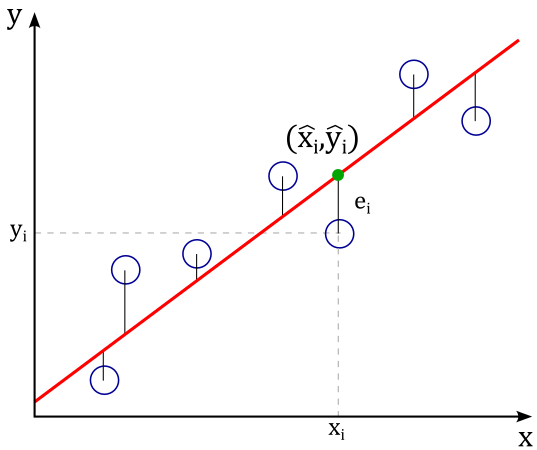

De las diferentes formas de estimar este error, existe una a partir de la cual podemos obtener una única recta para ese conjunto de datos, y se basa en considerar la suma del cuadrado de todos los errores,


$$S_r=\sum_{i=1}^ne_i^2=\sum_{i=1}^n(y_i-\hat{y_i})^2=\sum_{i=1}^n(y_i-a_0-a_1x_i)^2$$


para que de esta forma, las distancias entre las mediciones $y_i$ y el modelo lineal $\hat{y_i}$, puedan ser minimizada.

Debido a que buscamos una única recta cuya distancia sea mínima a todos los puntos, la ecuación antenrior se minimiza con respecto a los coeficientes $a_0$ y $a_1$, es decir, las derivadas parciales con respecto a estas variables deben ser cero. De estas derivadas se obtiene un sistema de dos ecuaciones a partir de las cuales se obtienen los valores para cada constante.


$$\frac{\partial S_r}{\partial a_0}=\sum y_i-\sum a_0-\sum a_1x_i=0$$



$$\frac{\partial S_r}{\partial a_1}=\sum y_ix_i-\sum a_0x_i-\sum a_1x_i^2=0$$


de donde 


$$a_0=\bar{y}-a_1\bar{x}$$



$$a_1=\frac{n\sum x_iy_i-\sum x_i\sum y_i}{n\sum x_i^2-(\sum x_i)^2}$$


% Datos proporcionados
x_lineal = [1, 2, 3, 4, 5, 6, 7];
y_lineal = [0.5, 2.5, 2.0, 4.0, 3.5, 6.0, 5.5];

% Cálculo de las sumas necesarias
n = length(x_lineal);
sum_x = sum(x_lineal);
sum_y = sum(y_lineal);
sum_xy = sum(x_lineal .* y_lineal);
sum_x2 = sum(x_lineal .^ 2);

% Cálculo de los coeficientes
b = (n * sum_xy - sum_x * sum_y) / (n * sum_x2 - sum_x^2);
a = (sum_y - b * sum_x) / n;

% Predicciones
y_pred = a + b * x_lineal;

% Cálculo del coeficiente de determinación R²
SS_res = sum((y_lineal - y_pred).^2);  % Suma de cuadrados de los residuos
SS_tot = sum((y_lineal - mean(y_lineal)).^2); % Suma de cuadrados total
R2 = 1 - (SS_res / SS_tot);     % Coeficiente de determinación

% Mostrar resultados
fprintf('Ecuación de la recta: y = %.4f + %.4fx\n', a, b);
fprintf('Coeficiente a (intercept): %.4f\n', a);
fprintf('Coeficiente b (pendiente): %.4f\n', b);
fprintf('Coeficiente de determinación R²: %.4f\n', R2);

% Predicción para x=8 como ejemplo
x_pred = 8;
y_pred = a + b * x_pred;
fprintf('Predicción para x=%d: y = %.4f\n', x_pred, y_pred);

% Gráfico de los datos y la recta de regresión
figure;
scatter(x_lineal, y_lineal, 'filled'); % Diagrama de dispersión de los datos
hold on;
plot(x_lineal, a + b*x_lineal, 'r');   % Línea de regresión
xlabel('x_i');
ylabel('y_i');
title(['Regresión Lineal (R² = ', num2str(R2, '%.4f'), ')']);
grid on;
legend('Datos', 'Ajuste lineal', 'Location', 'northwest');

Usando la función de ajuste de regresión lineal

% Datos
x_lineal = [1, 2, 3, 4, 5, 6, 7]';
y_lineal = [0.5, 2.5, 2.0, 4.0, 3.5, 6.0, 5.5]';

% Crear tabla de datos (requerido por fitlm)
tbl = table(x_lineal, y_lineal, 'VariableNames', {'x', 'y'});

% Ajustar modelo lineal
modelo = fitlm(tbl, 'y ~ x');
% Gráfico con línea de regresión
figure;
plot(modelo);
title('Regresión Lineal usando fitlm');
grid on;

En virtud de que la linea recta representa **una media** para todos los valores alrededro de ella, la desviación estandar de esta acumulación de puntos alerededor de la recta se obtiene de 


$$s=\sqrt{\frac{S_r}{n-2}}$$


el error estandar para los datos usados sin considerar las estimaciones de los coeficientes $a_0$ y $a_1$ debido a que estos corresponde a dos de los $n$ puntos usados en la estimación.

% Datos proporcionados
x_lineal = [1, 2, 3, 4, 5, 6, 7]';
y_lineal = [0.5, 2.5, 2.0, 4.0, 3.5, 6.0, 5.5]';

% 1. Regresión lineal
p = polyfit(x_lineal, y_lineal, 1);
y_pred = polyval(p, x_lineal);
residuos = y_lineal - y_pred;
sigma = std(residuos);

% 2. Crear figura principal
figure;
set(gcf, 'Position', [100, 100, 800, 600], 'Color', 'w');

% Gráfica principal
main_ax = axes('Position', [0.1 0.1 0.8 0.8]);
scatter(x_lineal, y_lineal, 'filled', 'b');
hold on;
plot(x_lineal, y_pred, 'r-', 'LineWidth', 2);
title(['Regresión Lineal: y = ', num2str(p(2), '%.4f'), ' + ', num2str(p(1), '%.4f'), 'x']);
xlabel('x_i');
ylabel('y_i');
grid on;
legend('Datos', 'Ajuste lineal', 'Location', 'northwest');
axis tight;

% 3. Crear distribución gaussiana para el inset
x_gauss = linspace(-3*sigma, 3*sigma, 200);
y_gauss = normpdf(x_gauss, 0, sigma);
y_gauss = y_gauss/max(y_gauss)*0.8; % Normalizar altura

% 4. Crear inset rotado
inset_pos = [0.6 0.61 0.25 0.25]; % Posición y tamaño del inset
inset_ax = axes('Position', inset_pos);

% Rotar y graficar la gaussiana (30 grados)
theta = -atand(p(1))-10; % Ángulo de rotación en grados

[x_rot, y_rot] = rotate_curve(x_gauss, y_gauss, theta);

fill(x_rot, y_rot, [0.7 0.7 0.7], 'FaceAlpha', 0.5, 'EdgeColor', 'k', 'LineWidth', 1);
hold on;

% Configurar el inset
set(inset_ax, 'Color', 'none', 'XTick', [], 'YTick', [], 'XColor', 'none', 'YColor', 'none');
axis equal;
axis off;

De la misma forma como se considera un valor medio con una desviación estándar para obtener una distribución sobre una estadística gaussiana, es posible obtener un coeficiente que nos nos de información de que tan grande es la diferencia entre los puntos del ajuste y la dispersión para cada uno de los datos con respecto al ajuste. A este parámetro se le conoce como *coeficiente de determinación. *

## Linealización

En ocasiones, encontraremos que los datos no siguen una tendencia lineal por lo que tendremos que modificarlos para que puedan visualizarse como una línea recta.

% Datos de la tabla
x_lineal = [1, 2, 3, 4, 5];
y_lineal = [0.5, 1.7, 3.4, 5.7, 8.4];

% Aplicar transformación logarítmica base 10 a y
x_log= log10(x_lineal);
y_log = log10(y_lineal);

% Ajuste lineal a los datos NO transformados
p_lineal = polyfit(x_lineal, y_lineal, 1);
a_lineal = p(2); % Intercepto
b_lineal = p(1); % Pendiente

% Ajuste lineal a los datos transformados
p = polyfit(x_log, y_log, 1);
a = p(2); % Intercepto
b = p(1); % Pendiente

% Crear figura con dos subgráficas
figure;

% Subgráfica 1: Datos originales
subplot(1,2,1);
scatter(x_lineal, y_lineal, 'filled', 'b');
hold on;
plot(x_lineal, polyval(p_lineal, x_lineal), 'b-', 'LineWidth', 1.5);
plot(x_lineal, y_lineal, 'b--');
title('Datos Originales');
xlabel('x');
ylabel('y');
grid on;
legend('Datos crudos', 'Location', 'northwest');

% Subgráfica 2: Datos transformados y ajuste lineal
subplot(1,2,2);
scatter(x_log, y_log, 'filled', 'r');
hold on;
plot(x_log, polyval(p, x_log), 'r-', 'LineWidth', 1.5);
title('Datos Linealizados (log_{10}(y) vs x)');
xlabel('x');
ylabel('log_{10}(y)');
grid on;
legend('Datos transformados', ['Ajuste lineal: ' sprintf('log_{10}(y) = %.3f + %.3fx', a, b)], ...
       'Location', 'none', 'Position', [0.8, .2, 0.3, 0.1]);

% Mostrar ecuación de ajuste
fprintf('Ecuación linealizada: log10(y) = %.4f + %.4f*x\n', a, b);
fprintf('Pendiente (b): %.4f\n', b);
fprintf('Intercepto (a): %.4f\n', a);

% Calcular R²
y_log_pred = polyval(p, x_log);
SS_res = sum((y_log - y_log_pred).^2);
SS_tot = sum((y_log - mean(y_log)).^2);
R2 = 1 - (SS_res / SS_tot);
fprintf('Coeficiente de determinación R²: %.4f\n', R2);

## Ajuste polinamial

En el caso de que la linealzación no sea la manera mas adecuada para transformar los datos, un ajuste polinomal sería lo mas adecuado. El numero de ecuaciones necesarias para minimizar el orden el error dependerá del grado del polinómino de tal forma que si el modelo tiene una forma


$$y=a_0+a_1x+a_2x^2+...+a_mx^m+e$$


entonces se necesitarían $m+1$ ecuaciones provenientes de las derivadas $\frac{\partial S_r}{\partial a_0},...\,,\frac{\partial S_r}{\partial a_m}$. Este problema está resuelto con la función *polifit*. 

# Ejercicio

De los datos proporcionados, calcula la aceleración y desaceleración promedio del metro entre dos estaciones.

% load("D:\Drive @gmail\MATLAB_Online\MobileSensorData/sensorlog_20250319_182513.mat")
% url = 'https://github.com/ArnaldoHC/Herramientas-Computacionales-Avanzadas/raw/498db9030cf94ace36e12014acb45b41873494b9/Clases/sensorlog_20250319_182513.mat';
url = 'https://github.com/ArnaldoHC/Herramientas-Computacionales-Avanzadas/raw/717fb51a62058a2968f76f8eea982ab7080e4252/Clases/aceleracion.dat';
filename = 'aceleracion.dat'; % Nombre local del archivo descargado
websave(filename, url);
load(filename)

x_ejem = aceleracion(: , 1);
y_ejem = aceleracion(: , 2);
z_ejem = aceleracion(: , 2);
t=[1:length(x_ejem)];

mag_a=sqrt(x_ejem.^2+y_ejem.^2+z_ejem.^2);
figure;
subplot(1,4,1)
plot(t,x_ejem)
subplot(1,4,2)
plot(t,y_ejem)
subplot(1,4,3)
plot(t,z_ejem)
subplot(1,4,4)
plot(t,mag_a)

function [xr, yr] = rotate_curve(x, y, theta)
    theta_rad = deg2rad(theta);
    rot_mat = [cos(theta_rad) -sin(theta_rad); sin(theta_rad) cos(theta_rad)];
    rotated = rot_mat * [x; y];
    xr = rotated(1,:);
    yr = rotated(2,:);
end